clear all,clc;
% test2:
% marginal v.s. maximum
load('my_test.mat')
cell_type = 4;
experiment_num = 8;
total_num = (cell_type-1)*10 + experiment_num;

output(total_num).maximum_likelihood.parameters

ans = struct with fields:
       theta_pref: 65
               Rp: 3.3472
               Rn: 2.9373
            sigma: 47.3471
              Rsp: 1
    tunning_curve: [360×1 double]

theta = 0:359;
marginal_theta_pref = output(total_num).marginal_likelihood.theta_pref.values(find(output(total_num).marginal_likelihood.theta_pref.likelihoods==max(output(total_num).marginal_likelihood.theta_pref.likelihoods)))

marginal_theta_pref = 65

marginal_rp = output(total_num).marginal_likelihood.Rp.values(find(output(total_num).marginal_likelihood.Rp.likelihoods==max(output(total_num).marginal_likelihood.Rp.likelihoods)))

marginal_rp = 3.3472

marginal_rn = marginal_rp * output(total_num).marginal_likelihood.Alpha.values(find(output(total_num).marginal_likelihood.Alpha.likelihoods==max(output(total_num).marginal_likelihood.Alpha.likelihoods)))

marginal_rn = 3.3472

marginal_sigma = output(total_num).marginal_likelihood.sigma.values(find(output(total_num).marginal_likelihood.sigma.likelihoods==max(output(total_num).marginal_likelihood.sigma.likelihoods)))

marginal_sigma = 90.0000

marginal_rsp = output(total_num).marginal_likelihood.Rsp.values(find(output(total_num).marginal_likelihood.Rsp.likelihoods==max(output(total_num).marginal_likelihood.Rsp.likelihoods)))

marginal_rsp = 1

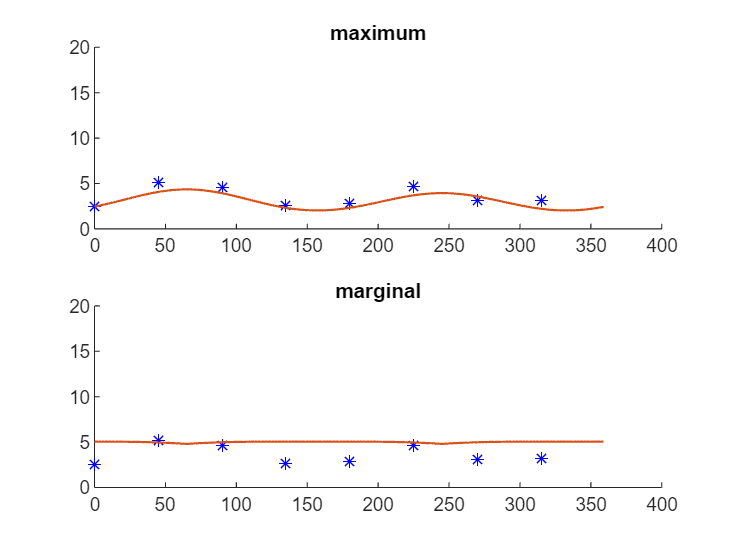

marginal_curve = marginal_rsp + marginal_rp * exp(-0.5*angdiff(theta-marginal_theta_pref).^2/marginal_sigma^2) + marginal_rn * exp(-0.5*angdiff(theta-marginal_theta_pref+180).^2/marginal_sigma^2);

tiledlayout flow
nexttile
hold on
plot(data_mean{cell_type}(experiment_num).angle,data_mean{cell_type}(experiment_num).mean_responses,'b*')
plot(0:359,output(total_num).maximum_likelihood.parameters.tunning_curve,LineWidth=1)
ylim([0 20])
title('maximum')

nexttile
hold on
plot(data_mean{cell_type}(experiment_num).angle,data_mean{cell_type}(experiment_num).mean_responses,'b*')
plot(0:359,marginal_curve,LineWidth=1)
ylim([0 20])
title('marginal')

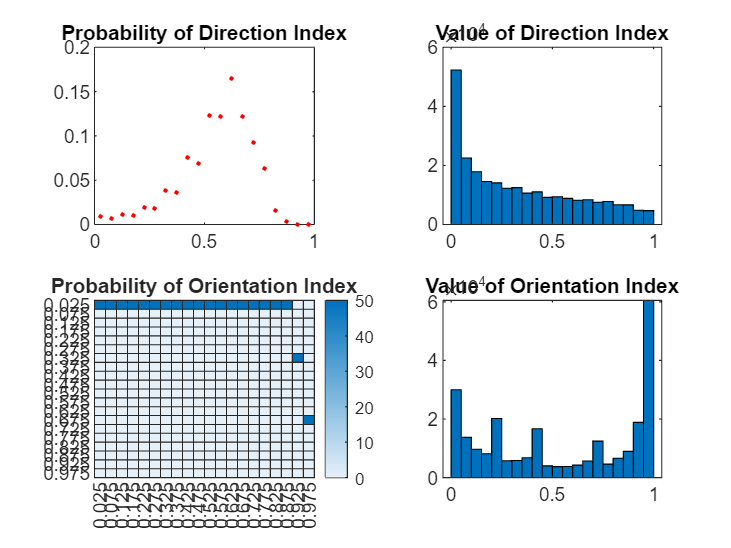

edges = 0:0.05:1;
center = edges(1:end-1) + (edges(1)+edges(2))/2;

[di_index] = discretize(output(total_num).descriptors.di.values(:),edges);
for bin = 1:max(di_index)
    F = di_index==bin;
    di_count(bin) = sum(F);
    di_lik_count(bin) = sum(output(total_num).descriptors.di.likelihoods(F));
end
di_lik_count = di_lik_count./sum(di_lik_count);

[oi_index] = discretize(output(total_num).descriptors.oi.values(:),edges);
for bin = 1:max(oi_index)
    F = oi_index==bin;
    oi_count(bin) = sum(F);
    oi_lik_count(bin) = sum(output(total_num).descriptors.oi.likelihoods(F));
end
oi_lik_count = oi_lik_count./sum(oi_lik_count);

% calculate heatmap 2-D matrix

oi_lik_heatmap = zeros(length(edges)-1,length(oi_lik_count));
lik_heatmap = oi_lik_heatmap;
for total_num = 1:length(output)
    oi_lik_index = discretize(oi_lik_count,edges);
    for oi_bin = 1:length(oi_lik_count)
        lik_heatmap(oi_lik_index(oi_bin),oi_bin) = 1;
    end
    oi_lik_heatmap = oi_lik_heatmap + lik_heatmap;
end

%plot
tiledlayout flow
nexttile
plot(center,di_lik_count,'r.')
title('Probability of Direction Index')

nexttile
bar(center,di_count,1)
title('Value of Direction Index')

nexttile
heatmap(center,center,oi_lik_heatmap)
title('Probability of Orientation Index')

nexttile
bar(center,oi_count,1)
title('Value of Orientation Index')

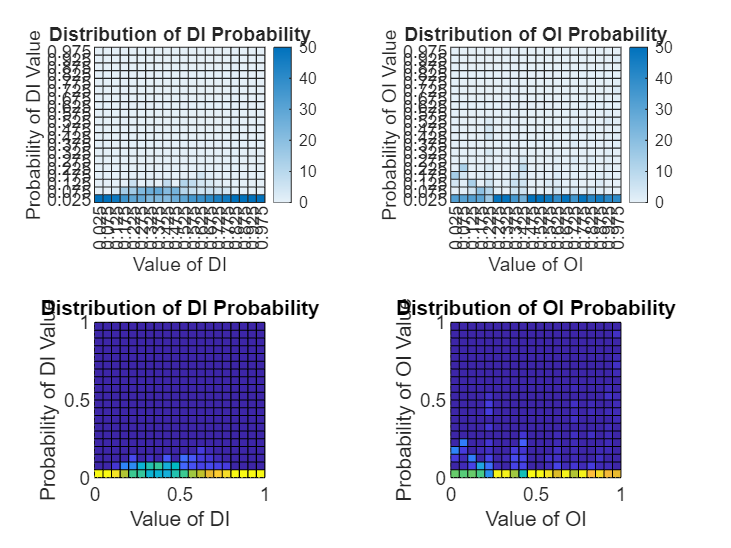

[di_index] = discretize(output(total_num).descriptors.di.values(:),0:0.05:1);
[oi_index] = discretize(output(total_num).descriptors.oi.values(:),0:0.05:1);
oi_lik_heatmap = zeros(length(edges)-1,length(oi_lik_count));
di_lik_heatmap = zeros(length(edges)-1,length(di_lik_count));
lik_heatmap = oi_lik_heatmap;

tiledlayout flow
nexttile,hold on
for total_num = 1:50
    for bin = 1:max(di_index)
        F = di_index==bin;
        di_count(bin) = sum(F);
        di_lik_count(bin) = sum(output(total_num).descriptors.di.likelihoods(F));
    end
    di_lik_count = di_lik_count./sum(di_lik_count);
    [di_lik_index] = discretize(di_lik_count(:),0:0.05:1);
        for bin = 1:max(di_lik_index)
        F = di_lik_index==bin;
        di_lik_count(bin) = sum(output(total_num).descriptors.di.likelihoods(F));
    end
    plot(.025:.05:1,di_lik_count,'b.')
    % calculate heatmap 2-D matrix

    di_lik_index = discretize(di_lik_count,edges);
    for di_bin = 1:length(di_lik_count)
        lik_heatmap(di_lik_index(di_bin),di_bin) = 1;
    end
    di_lik_heatmap = di_lik_heatmap + lik_heatmap;
    lik_heatmap(:) = 0;
end
xlabel('Underlying DI')
ylabel('Probability')
ylim([0 1])
title('Probability of Direction Index')

nexttile,hold on
for total_num = 1:length(output)
    [oi_index] = discretize(output(total_num).descriptors.oi.values(:),0:0.05:1);
    for bin = 1:max(oi_index)
        F = oi_index==bin;
        oi_count(bin) = sum(F);
        oi_lik_count(bin) = sum(output(total_num).descriptors.oi.likelihoods(F));
    end
    oi_lik_count = oi_lik_count./sum(oi_lik_count);
    plot(.025:.05:1,oi_lik_count,'r.')
    % calculate heatmap 2-D matrix

    oi_lik_index = discretize(oi_lik_count,edges);
    for oi_bin = 1:length(oi_lik_count)
        lik_heatmap(oi_lik_index(oi_bin),oi_bin) = 1;
    end
    oi_lik_heatmap = oi_lik_heatmap + lik_heatmap;
    lik_heatmap(:) = 0;
end
xlabel('Underlying OI')
ylabel('Probability')
ylim([0 1])
title('Probability of Orientation Index')

tiledlayout flow
nexttile,
heatmap(center,flip(center),flip(di_lik_heatmap,1))
xlabel('Value of DI')
ylabel('Probability of DI Value')
title('Distribution of DI Probability')

nexttile,
heatmap(center,flip(center),flip(oi_lik_heatmap,1))
xlabel('Value of OI')
ylabel('Probability of OI Value')
title('Distribution of OI Probability')

nexttile,
di_lik_pcolor = [di_lik_heatmap;zeros(1,length(di_lik_count))];
di_lik_pcolor = [di_lik_pcolor,zeros(length(edges),1)];
pcolor(edges,edges,di_lik_pcolor)
xlabel('Value of DI')
ylabel('Probability of DI Value')
title('Distribution of DI Probability')

nexttile,
oi_lik_pcolor = [oi_lik_heatmap;zeros(1,length(oi_lik_count))];
oi_lik_pcolor = [oi_lik_pcolor,zeros(length(edges),1)];
pcolor(edges,edges,oi_lik_pcolor)
xlabel('Value of OI')
ylabel('Probability of OI Value')
title('Distribution of OI Probability')

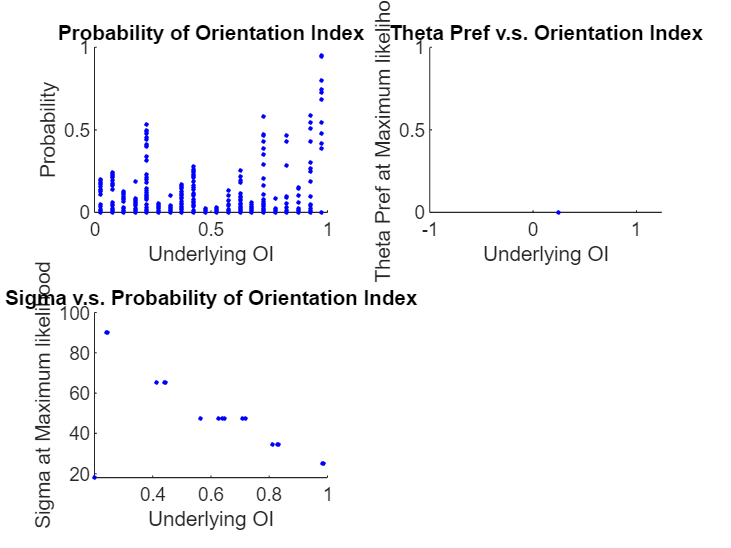

tiledlayout flow
nexttile,hold on
for total_num = 1:50
    [oi_index] = discretize(output(total_num).descriptors.oi.values(:),0:0.05:1);
for bin = 1:max(oi_index)
    F = oi_index==bin;
    oi_count(bin) = sum(F);
    oi_lik_count(bin) = sum(output(total_num).descriptors.oi.likelihoods(F));
end
oi_lik_count = oi_lik_count./sum(oi_lik_count);
plot(.025:.05:1,oi_lik_count,'b.')
end
xlabel('Underlying OI')
ylabel('Probability')
ylim([0 1])
title('Probability of Orientation Index')

nexttile,hold on
for total_num = 1:50
    plot(output(total_num).maximum_likelihood.descriptors.oi,output(total_num).maximum_likelihood.parameters.theta_pref,'b.')
end
xlabel('Underlying OI')
ylabel('Theta Pref at Maximum likelihood')
ylim([0 1])
title('Theta Pref v.s. Orientation Index')

nexttile,hold on
for total_num = 1:50
    plot(output(total_num).maximum_likelihood.descriptors.oi,output(total_num).maximum_likelihood.parameters.sigma,'b.')
end
xlabel('Underlying OI')
ylabel('Sigma at Maximum likelihood')
title('Sigma v.s. Probability of Orientation Index')